% AAE 364L LAB4 MATLAB CODE
% TOMOKI KOIKE
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Load result data

pos = load("koike_lab4\koike_lab4_xc.mat");
angle = load("koike_lab4\koike_lab4_theta.mat");

% PP

t = pos.x_and_coimmand_part3.time;
xc = pos.x_and_coimmand_part3.signals.values(:,1);
command = pos.x_and_coimmand_part3.signals.values(:,2);
theta = angle.theta_part3.signals.values;

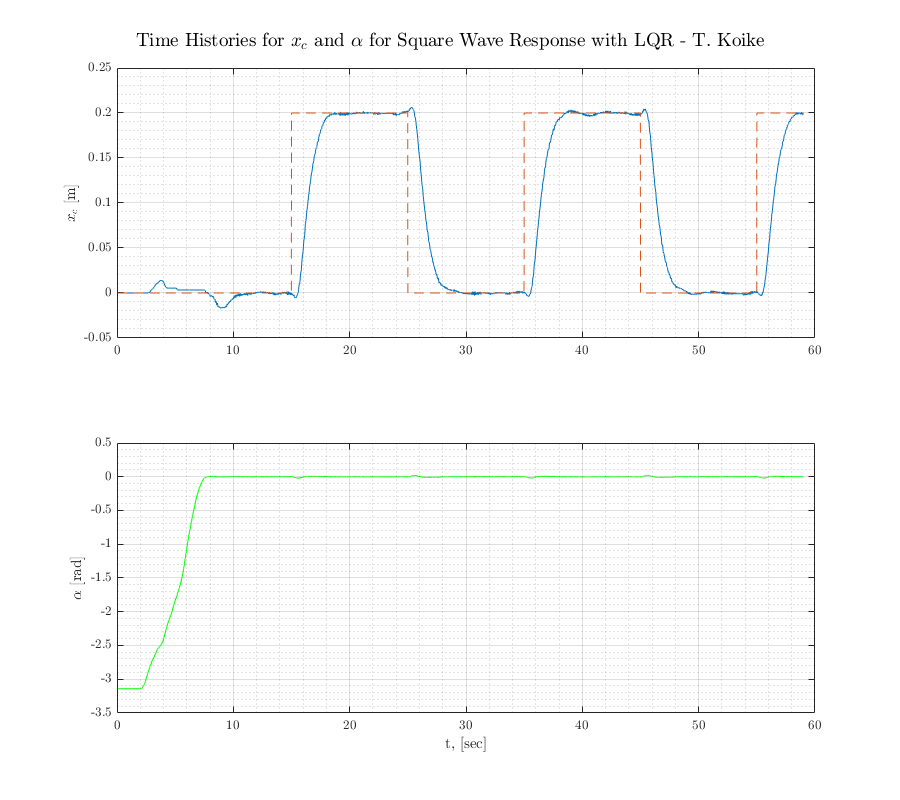

% Plotting 
fig = figure('Renderer',"painters", 'Position', [10 10 900 800]);
subplot(2,1,1)
plot(t,xc)
grid on; grid minor; box on; hold on;
plot(t, command, '--')
hold off
ylabel('$x_c$ [m]')
subplot(2,1,2)
plot(t,theta, '-g')
grid on; grid minor; box on;
ylabel('$\alpha$ [rad]')
xlabel('t, [sec]')
sgtitle('Time Histories for $x_c$ and $\alpha$ for Square Wave Response with LQR - T. Koike')
saveas(fig, 'response.png')